# Fltraggio Online ed Offline

Il filtro online opera direttamente sul segnale temporale elaborandolo mano mano che esso si presenta, campione dopo campione tramite una successione per ricorrenza. La dimostrazione del fatto che si ha una successione per ricorrenza la si ottiene:

- moltiplicando la trasformata di un segnale per una funzione di trasferimento del primo ordine

- antitrasformando

- discretizzando la derivata con formula di Eulero

Vi sono diverse tipologie di filtri già disponibili in matlab.

Il filtro offline invece opera come segue:

- calcola la FFT

- applica una maschera che riduce le componenti indesiderate

- antitrasforma


% PROVARE A CAMBIARE LE COMPONENTI DI RUMORE ED IL TIPO DI FILTRO
close all
clear all
clc

Generazione del Segnale

Tc = 0.01;          % fc = 100 Hz
t = 0:Tc:50;
ss = length(t);
s = sin(2*pi*t/5);  % periodo 5 s

Calcolo e Rappresentazione della Trasformata

s_FFT = fft(s);
% f = ( 0: floor(length(t)/2) )* 1/max(t);  % Notare la risoluzione in frequenza = 1/TempoTotaleAck
ff = 0:1/max(t):1/Tc;

Plot del segnale e dello spettro corrispondente:

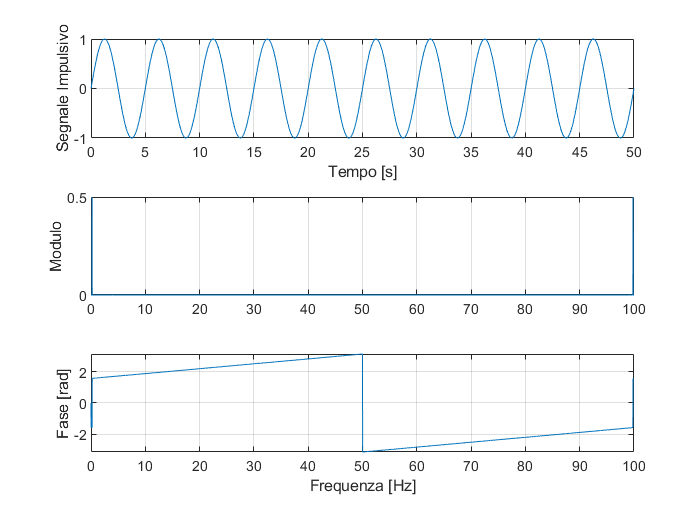

subplot(3,1,1), plot(t , s ), ylabel('Segnale Impulsivo'), grid on
xlabel('Tempo [s]')
subplot(3,1,2), plot(ff , abs(s_FFT)/ss), ylabel('Modulo'), grid on
subplot(3,1,3), plot(ff , angle(s_FFT)), ylabel('Fase [rad]')
xlabel('Frequenza [Hz]'), grid on

Aggiunta di Rumore

s = s + 0.3*sin(2*pi*t/0.25) + 0.2*sin(2*pi*t/0.1) + 0.3*randn(size(t));

s_FFT = fft(s);

Plot del segnale e dello spettro corrispondente:

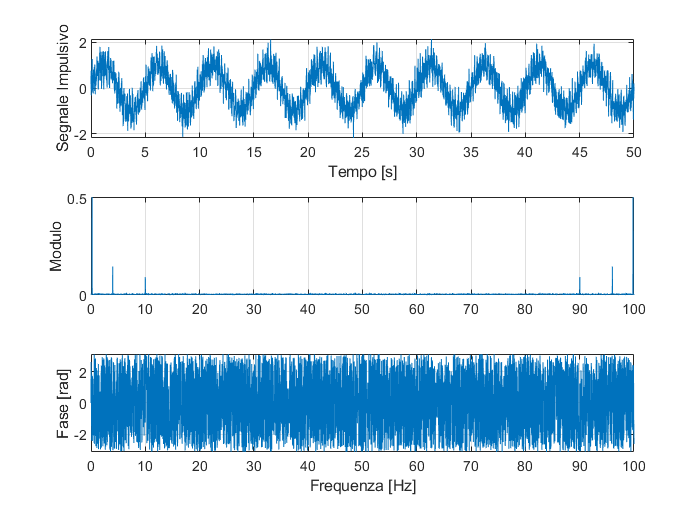

figure
subplot(3,1,1), plot(t , s ), ylabel('Segnale Impulsivo'), grid on
xlabel('Tempo [s]')
subplot(3,1,2), plot(ff , abs(s_FFT)/ss), ylabel('Modulo'), grid on
subplot(3,1,3), plot(ff , angle(s_FFT)), ylabel('Fase [rad]')
xlabel('Frequenza [Hz]'), grid on

## Filtro post processing

Costruzione del filtro in frequenza

% Si costruisce la parte corrispondente alle frequenze positive:
filtro = exp(-0.5 * ff(1:ceil(end/2)).^2);  % Notare che e' un vettore reale

% Si aggiunge la parte corrispondente alle frequenze negative (in coda e invertita)
% facendo attenzione al fatto che il primo campione deve corrispondere alla 
% continua mentre l'ultimo alla prima componente negativa (ovvero la componente
% continua non si ripete nello spettro; a tale proposito si analizzi attentamente la
% figura della Trasformata di Fourier del segnale):
filtroNeg =  fliplr(filtro) ;
filtroNeg = filtroNeg(1:end-1) ;
filtro = [filtro filtroNeg] ;


Filtro Post Processing:

sfft_F = s_FFT .* filtro ;

Per la rappresentazione, costruiamo la base delle frequenze come si usa fare da -inf a +inf

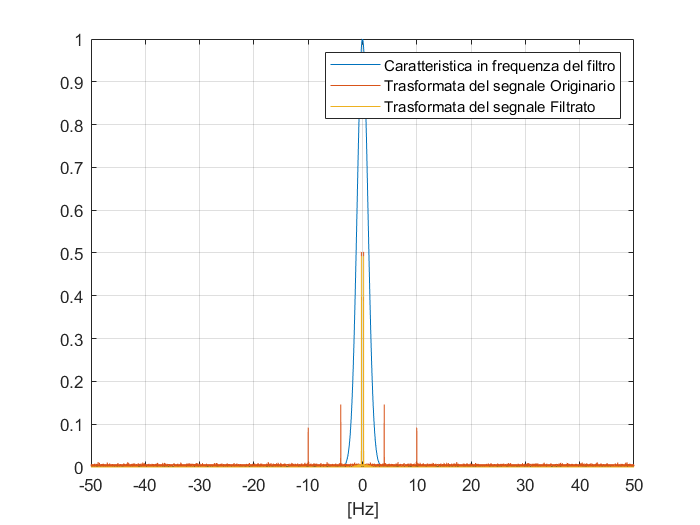

f = ( 0: floor(length(t)/2) ) * 1/max(t);
fplot = [f -fliplr(f(2:end))];

figure, plot(fplot, filtro,   fplot, abs(s_FFT)/ss, fplot, abs(sfft_F)/ss)
xlabel('[Hz]'), grid on
legend('Caratteristica in frequenza del filtro' , 'Trasformata del segnale Originario', 'Trasformata del segnale Filtrato')

Calcoliamo il risultato nel tempo del filtraggio

s_F = ifft(sfft_F);

Rappresentazione del segnale corrotto da rumore, di quello filtrato e di quello originario

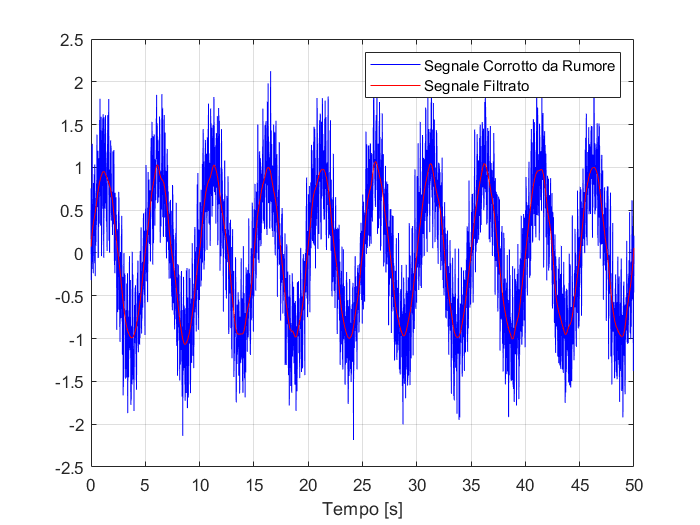

figure, plot(t,s, 'b', t,s_F ,'r'), grid on, 
xlabel('Tempo [s]'), legend('Segnale Corrotto da Rumore' , 'Segnale Filtrato')

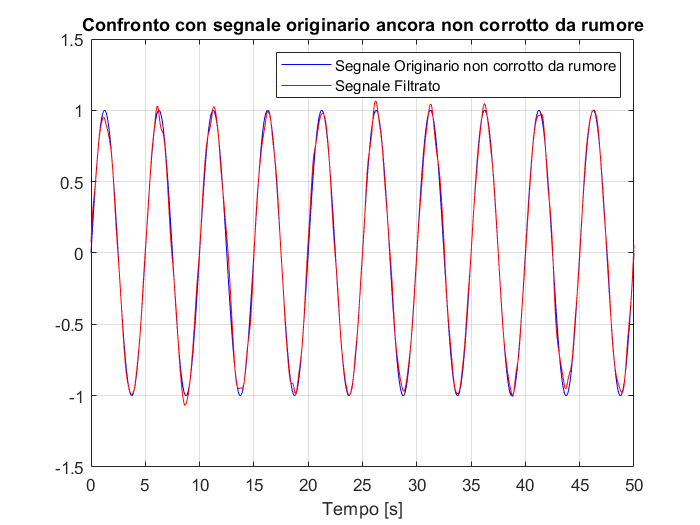

% figure, plot(imag(s_F)), title('Residui immaginari nella antitrasformata')

figure, plot(t,sin(2*pi*t/5), 'b', t,s_F ,'r'), title('Confronto con segnale originario ancora non corrotto da rumore'), grid on, 
xlabel('Tempo [s]'), legend('Segnale Originario non corrotto da rumore' , 'Segnale Filtrato')

## Filtro on-line

fN = 0.5 / Tc;      % Frequenza di Nyquist

Si guardi lo spettro del segnare con rumore e si scelga una frequenza di taglio capace di togliere le componenti di disturbo e mantenere quella del segnale

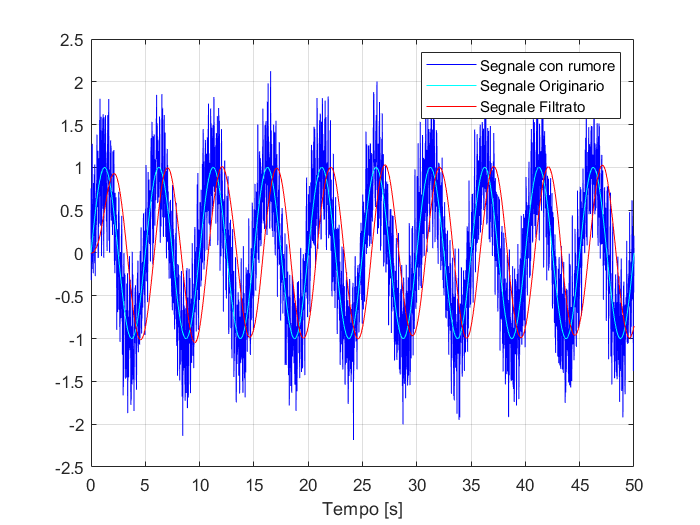

fT = 0.4 / fN;      % Frequenza di taglio sempre riferita alla fN

[B,A] = butter(3, fT) ;
s_Fonline = filter(B, A, s) ;

% spiega la successione per ricorrenza che viene fuori dalla digitalizzazione
% dell'equazione differenziale nel tempo (1 / 1+i w tau)

figure, plot(t,s, 'b', t,sin(2*pi*t/5), 'c', t,s_Fonline ,'r')
grid on, xlabel('Tempo [s]')
legend('Segnale con rumore', 'Segnale Originario' , 'Segnale Filtrato')


% prova:
% - ordini diversi filtro
% - frequenze taglio diverse
% - filtri diversi
% - funzione filtfilt